clc;
clear;
Dsn=3.9e-14;
Dsp=1e-13;

Rsn=12.5e-6;
Rsp=8e-6;

epssn=0.471;
epssp=0.297;

Ln=100e-6;
Ls=52e-6;
Lp=183e-6;

Lsum=Ln+Ls+Lp;

cs0neg=14870;
cs0pos=3900;

csmaxneg=26390;
csmaxpos=22860;

A=1;
Rohm=6e-3;

F=96485.33289;

Qn=A*Ln*epssn*csmaxneg*F/3600;  %Ah
Qp=A*Lp*epssp*csmaxpos*F/3600;  %Ah

soc0n=cs0neg/csmaxneg;
soc0p=cs0pos/csmaxpos;

I=-17.5*[ones(3590,1)];
Jn=I*Rsn/3/epssn/F/A/Ln;
Jp=-I*Rsp/3/epssp/F/A/Lp;
I_cc=-17.5*[ones(2000,1);zeros(300,1);-ones(2000,1);zeros(3700,1)];
Jn_cc=I_cc*Rsn/3/epssn/F/A/Ln;
Jp_cc=-I_cc*Rsp/3/epssp/F/A/Lp;
load comsol_data\dst\dst.txt;
I_dst=17.5*dst(:,2);
Jn_dst=I_dst*Rsn/3/epssn/F/A/Ln;
Jp_dst=-I_dst*Rsp/3/epssp/F/A/Lp;
load comsol_data\fuds\fuds.txt;
I_fuds=17.5*fuds(:,2);
Jn_fuds=I_fuds*Rsn/3/epssn/F/A/Ln;
Jp_fuds=-I_fuds*Rsp/3/epssp/F/A/Lp;
load comsol_data\nedc\nedc.txt;
I_nedc=17.5*nedc(:,2);
Jn_nedc=I_nedc*Rsn/3/epssn/F/A/Ln;
Jp_nedc=-I_nedc*Rsp/3/epssp/F/A/Lp;

% nxdata{1,1}=Jn_cc';
% nxdata{2,1}=Jn_dst';
% nxdata{3,1}=Jn_fuds';
% nxdata{4,1}=Jn_nedc';
% nxdata{5,1}=Jn';

load comsol_data\load\dcsen_load.txt;
load comsol_data\load\dcsep_load.txt;

load comsol_data\cc\dcsen_cc.txt;
% nydata{1,1}=dcsen_cc(:,2)';
load comsol_data\dst\dcsen_dst.txt;
% nydata{2,1}=dcsen_dst(:,2)';
load comsol_data\fuds\dcsen_fuds.txt;
% nydata{3,1}=dcsen_fuds(:,2)';
load comsol_data\nedc\dcsen_nedc.txt;
% nydata{4,1}=dcsen_nedc(:,2)';
load comsol_data\load\dcsen_load.txt;
% nydata{5,1}=dcsen_load(:,2)';

load comsol_data\cep_load.txt;
cep=cep_load(:,2);
load comsol_data\cen_load.txt;
cen=cen_load(:,2);

layers=[
    sequenceInputLayer(1)
    lstmLayer(512,'OutputMode','sequence')
    fullyConnectedLayer(128)
    fullyConnectedLayer(1)
    regressionLayer]

layers =   具有以下层的 5×1 Layer 数组:

     1   ''   序列输入   序列输入: 1 个维度
     2   ''   LSTM     LSTM: 512 个隐藏单元
     3   ''   全连接     128 全连接层
     4   ''   全连接     1 全连接层
     5   ''   回归输出   mean-squared-error


maxEpochs = 500;
miniBatchSize = 1;

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'InitialLearnRate',0.005, ...
    'MiniBatchSize',miniBatchSize, ...
    'GradientThreshold',1, ...
    'Shuffle','never', ...
    'Plots','training-progress',...
    'Verbose',0);
[net_sn,info_sn]= trainNetwork(Jn',dcsen_load(:,2)',layers,options);

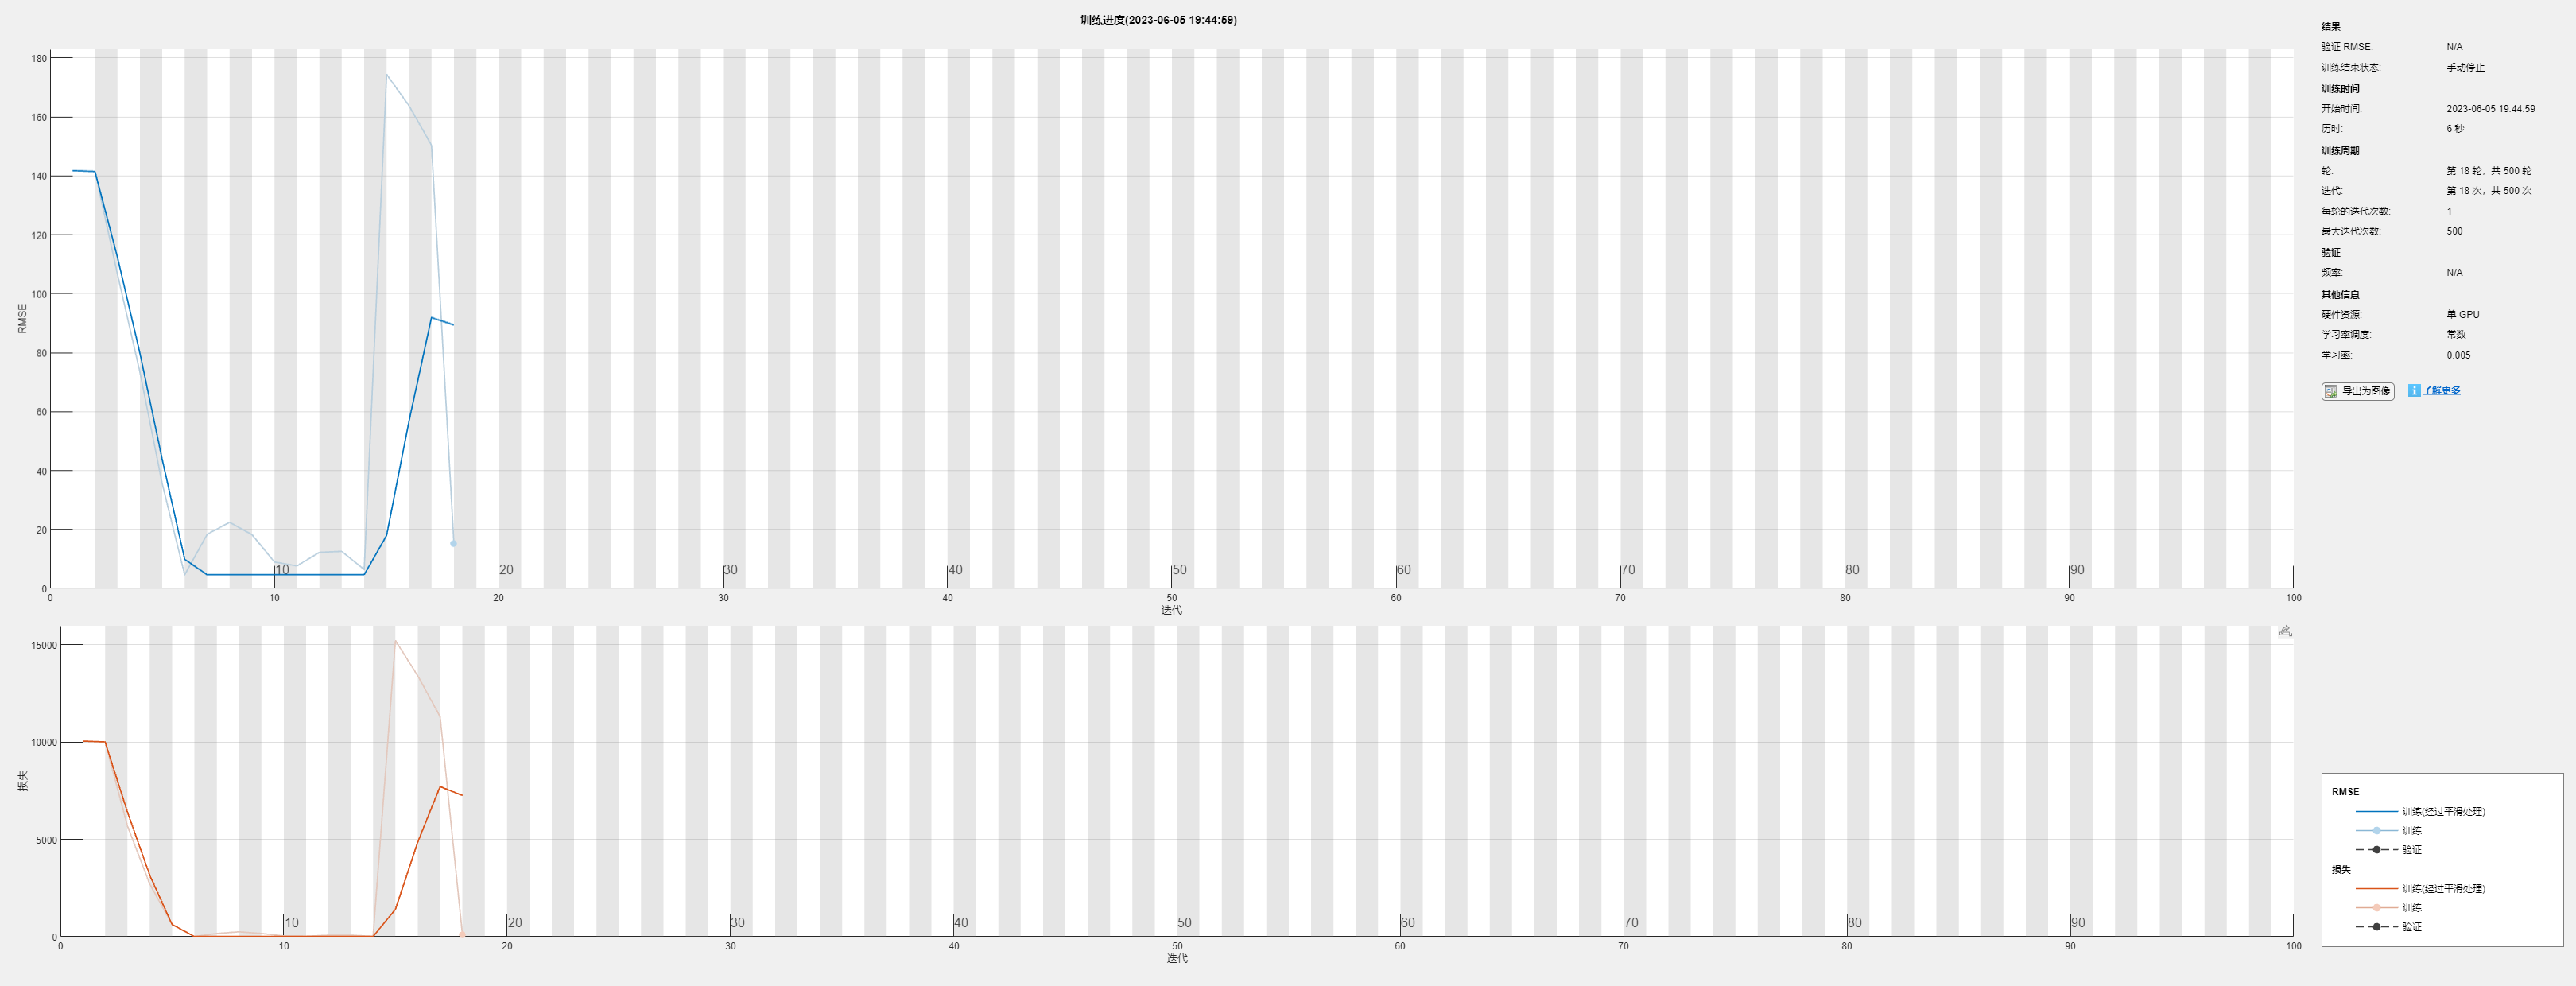

[net_sp,info_sp]= trainNetwork(Jp',dcsep_load(:,2)',layers,options);

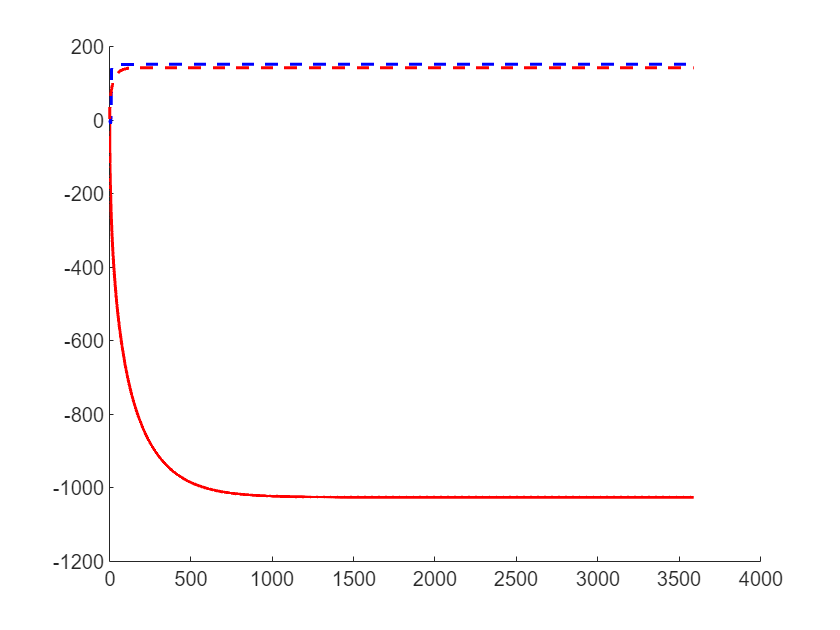

[net_en,info_en]= trainNetwork(Jn',cen',layers,options);
[net_ep,info_ep]= trainNetwork(Jp',cep',layers,options);

% load net_sn.mat;
Ypredn=predict(net_sn,Jn');
Ypredp=predict(net_sp,Jp');
Ycen=predict(net_en,Jn');
Ycep=predict(net_ep,Jp');
figure(2);
clf;
hold on;
plot(Ypredn,'b',LineWidth=1.5);
plot(dcsen_load(:,2)','r',LineWidth=1.5);
plot(Ypredp,'b--',LineWidth=1.5);
plot(dcsep_load(:,2)','r--',LineWidth=1.5);

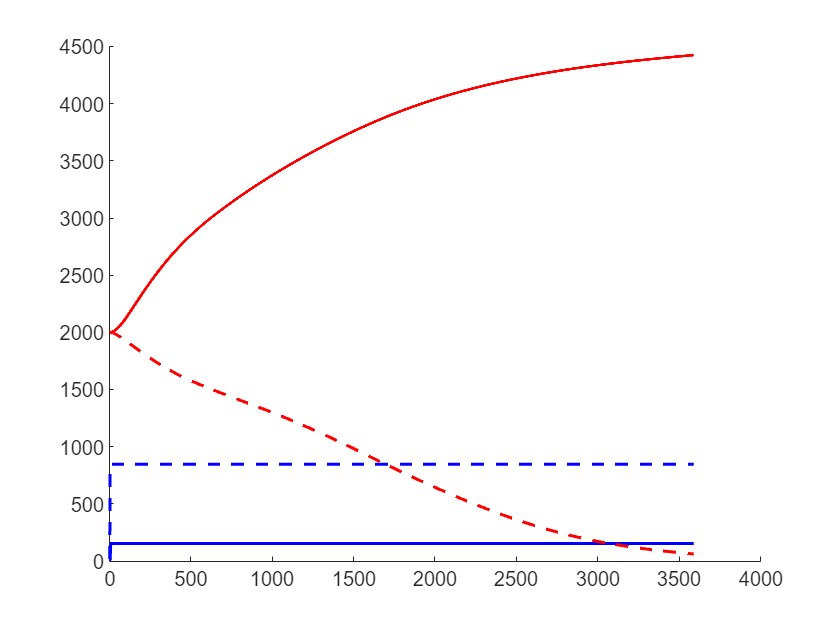


figure(3);
clf;
hold on;
plot(Ycen,'b',LineWidth=1.5);
plot(cen','r',LineWidth=1.5);
plot(Ycep,'b--',LineWidth=1.5);
plot(cep','r--',LineWidth=1.5);

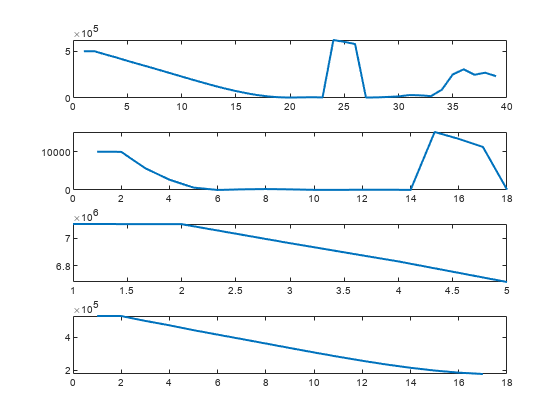


figure(4);
clf;
subplot(411);
plot(info_sn.TrainingLoss,LineWidth=1.5);
subplot(412);
plot(info_sp.TrainingLoss,LineWidth=1.5);
subplot(413);
plot(info_en.TrainingLoss,LineWidth=1.5);
subplot(414);
plot(info_ep.TrainingLoss,LineWidth=1.5);


% RMSE(Ypred,dcsen_cc(:,2))

function xdata=normzero(data)
mu=mean(data,2);
sig=std(data,0,2);
xdata=(data-mu)./sig;
end